%% ADOM Function
function destriped = ADOM(O, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter, direction)
    % ADOM: ADMM-Based Optimization Model for Stripe Noise Removal in Specified Direction
    % Input: O - observed image (2D matrix)
    %        lambda1, lambda2 - regularization parameters
    %        rho1, rho2, rho3 - penalty parameters
    %        p - threshold for acceleration adjustment
    %        tol - tolerance for convergence
    %        max_iter - maximum iterations
    %        direction - 'vertical', 'horizontal', or 'diagonal'
    % Output: destriped - destriped image (O - S)

    % Default parameters
    if nargin < 10, direction = 'vertical'; end
    if nargin < 9, max_iter = 200; end
    if nargin < 8, tol = 1e-4; end
    if nargin < 7, p = 10; end
    if nargin < 6, rho3 = 1; end
    if nargin < 5, rho2 = 1; end
    if nargin < 4, rho1 = 1; end
    if nargin < 3, lambda2 = 0.1; end
    if nargin < 2, lambda1 = 0.1; end

    [h, w] = size(O);
    delta = 0.1; % As per paper


    % Initialization
    S = zeros(h, w);
    S_prev = S;
    tau1 = zeros(h, w);
    tau2 = zeros(h, w);
    tau3 = zeros(h, w);
    alpha = 1;
    alpha_prev = alpha;
    wn = 1;
    k = 0;

    % Frequency domain setup for FFT solver
    [Fx, Fy] = meshgrid(0:w-1, 0:h-1);

    % Configure shifts and group handling based on direction
    switch lower(direction)
        case 'vertical'
            shift_along = [1, 0]; % Vertical gradient
            shift_perp = [0, 1];  % Horizontal gradient
            group_type = 'column';
            num_groups = w;
            get_group = @(S, g) S(:, g);
            set_group = @(C, v, g) assign_column(C, v, g);
            adj_diff = @(g1, g2) norm(g1 - g2, 2);
        case 'horizontal'
            shift_along = [0, 1]; % Horizontal gradient
            shift_perp = [1, 0];  % Vertical gradient
            group_type = 'row';
            num_groups = h;
            get_group = @(S, g) S(g, :);
            set_group = @(C, v, g) assign_row(C, v, g);
            adj_diff = @(g1, g2) norm(g1 - g2, 2);
        case 'diagonal'
            shift_along = [1, 1]; % Diagonal gradient
            shift_perp = [1, -1]; % Perpendicular to diagonal
            group_type = 'diagonal';
            ks = -(w-1):(h-1);
            num_groups = length(ks);
            idxs = cell(1, num_groups);
            for g = 1:num_groups
                k = ks(g);
                rows = max(1, 1+k):min(h, w+k);
                cols = rows - k;
                valid = cols >= 1 & cols <= w;
                rows = rows(valid);
                cols = cols(valid);
                idxs{g} = sub2ind([h, w], rows, cols);
            end
            get_group = @(S, g) S(idxs{g});
            set_group = @(C, v, g) assign_diagonal(C, v, idxs{g});
            adj_diff = @(g1, g2) abs(norm(g1, 2) - norm(g2, 2)); % Approximation for diagonals
        otherwise
            error('Unsupported direction. Choose ''vertical'', ''horizontal'', or ''diagonal''.');
    end


    % Helper functions for assignment
    function C = assign_column(C, v, g)
        C(:, g) = v;
    end
    function C = assign_row(C, v, g)
        C(g, :) = v;
    end
    function C = assign_diagonal(C, v, idx)
        C(idx) = v;
    end

    % Initialize weights
    wg = ones(1, num_groups);

    % Compute Fourier multipliers
    exp_along = exp(-1i * 2 * pi * (shift_along(1) * Fy / h + shift_along(2) * Fx / w));
    F_along = 1 - exp_along;
    F_along_conj = conj(F_along);

    exp_perp = exp(-1i * 2 * pi * (shift_perp(1) * Fy / h + shift_perp(2) * Fx / w));
    F_perp = 1 - exp_perp;
    F_perp_conj = conj(F_perp);

    Q = rho1 * (F_along_conj .* F_along) + rho2 * (F_perp_conj .* F_perp) + rho3;
    Q(Q == 0) = eps; % Avoid division by zero


    while k < max_iter
        k = k + 1;

        % 1. Weight control
        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev == 0
            gamma = 0;
        else
            gamma = norm(res_curr - res_prev, 'fro') / norm_res_prev;
        end
        if alpha ~= gamma % Correct comparison operator
            wn = (alpha_prev + gamma) / (alpha - gamma);
        else
            wn = 1;
        end
        % Update wg
        group_norms = zeros(1, num_groups);
        for g = 1:num_groups
            group_vec = get_group(S, g);
            group_norms(g) = norm(group_vec, 2);
        end
        v = sum(group_norms) / num_groups;
        for g = 1:num_groups
            update_flag = true;
            group_curr = get_group(S, g);
            if g > 1
                group_prev = get_group(S, g - 1);
                if adj_diff(group_curr, group_prev) >= v
                    update_flag = false;
                end
            end
            if g < num_groups
                group_next = get_group(S, g + 1);
                if adj_diff(group_curr, group_next) >= v
                    update_flag = false;
                end
            end
            if update_flag
                norm_shift = norm(group_curr + gamma, 2);
                if norm_shift > 0
                    wg(g) = 1 / (2 * norm_shift);
                end
            end
        end

 

       % 2. Evidence-based starting point control
        alpha_prev = alpha;
        if k <= p
            alpha = (1 + sqrt(1 + 4 * alpha_prev^2)) / 2;
        else
            alpha = (1 + sqrt(1 + 2 * alpha_prev^2)) / 2;
        end
        if k <= p
            d = wn;
        else
            d = alpha_prev / alpha;
        end


        % 3. Momentum-based step-size control
        if alpha_prev ~= 0
            S = S + ((alpha - delta) / alpha_prev) * (S - S_prev);
        end
        tau1 = d * tau1;
        tau2 = d * tau2;
        tau3 = d * tau3;


        % 4. ADMM-based subproblem solving
        % Compute gradients (assuming periodic boundaries)
        grad_along_S = S - circshift(S, shift_along);
        grad_perp_S = S - circshift(S, shift_perp);
        grad_perp_O = O - circshift(O, shift_perp);

        % Subproblem A
        temp = grad_along_S + tau1 / rho1;
        A = sign(temp) .* max(abs(temp) - 1 / rho1, 0);

        % Subproblem B
        temp = grad_perp_O - grad_perp_S + tau2 / rho2;
        B = sign(temp) .* max(abs(temp) - (wn * lambda1 / rho2), 0);

        % Subproblem C
        eta = S + tau3 / rho3;
        C = zeros(h, w);
        for g = 1:num_groups
            eta_group = get_group(eta, g);
            norm_eta = norm(eta_group, 2);
            thresh = wg(g) * lambda2 / rho3;
            if norm_eta > thresh
                c_group = eta_group * (norm_eta - thresh) / norm_eta;
                C = set_group(C, c_group, g);
            end
        end

        % Subproblem S
        rhs1 = A - tau1 / rho1;
        rhs2 = grad_perp_O - B + tau2 / rho2;
        rhs3 = C - tau3 / rho3;
        % FFT
        P = rho1 * F_along_conj .* fft2(rhs1) + rho2 * F_perp_conj .* fft2(rhs2) + rho3 * fft2(rhs3);
        S_new = real(ifft2(P ./ Q));


        % 5. Update Lagrange multipliers
        grad_along_Snew = S_new - circshift(S_new, shift_along);
        grad_perp_Snew = S_new - circshift(S_new, shift_perp);
        tau1 = tau1 + rho1 * (grad_along_Snew - A);
        tau2 = tau2 + rho2 * (grad_perp_O - grad_perp_Snew - B);
        tau3 = tau3 + rho3 * (S_new - C);

        % Update S_prev
        S_prev = S;
        S = S_new;

        % Convergence check
        res_curr = O - S;
        res_prev = O - S_prev;
        norm_res_prev = norm(res_prev, 'fro');
        if norm_res_prev > 0 && norm(res_curr - res_prev, 'fro') / norm_res_prev <= tol
            break;
        end
    end

    destriped = O - S;
end


%% Example Usage
% Load a test image (assuming you have an image; here we add synthetic stripes to a grayscale image)

% Load example image (replace with your image path)
img = imread("C:\Users\Mahallakshmi\OneDrive\Documents\S3_projects\Mfc_S3\Image.jpg"); % Update path as needed
if size(img,3) > 1
    img = rgb2gray(img);
end
O = im2double(img);

% Add synthetic stripes in all directions (non-periodical)
stripe_ratio = 0.4; % 40% of lines/diagonals affected
noise_intensity = 0.3; % Reduced intensity for better visibility (adjust as needed)
[h, w] = size(O);

% Vertical stripes
stripes_v = zeros(h, w);
num_stripes_v = round(stripe_ratio * w);
stripe_cols = randperm(w, num_stripes_v);
for col = stripe_cols
    stripes_v(:, col) = (rand() * 2 - 1) * noise_intensity;
end

% Horizontal stripes
stripes_h = zeros(h, w);
num_stripes_h = round(stripe_ratio * h);
stripe_rows = randperm(h, num_stripes_h);
for row = stripe_rows
    stripes_h(row, :) = (rand() * 2 - 1) * noise_intensity;
end

% Diagonal stripes
stripes_d = zeros(h, w);
ks = -(w-1):(h-1);
num_diags = length(ks);
num_stripes_d = round(stripe_ratio * num_diags);
stripe_diags = randperm(num_diags, num_stripes_d);
for g = stripe_diags
    k = ks(g);
    rows = max(1, 1+k):min(h, w+k);
    cols = rows - k;
    valid = cols >= 1 & cols <= w;
    rows = rows(valid);
    cols = cols(valid);
    idx = sub2ind([h, w], rows, cols);
    constant = (rand() * 2 - 1) * noise_intensity;
    stripes_d(idx) = constant;
end

% Combine stripes
O_striped = O + stripes_v + stripes_h + stripes_d;
O_striped = max(0, min(1, O_striped)); % Clip to [0,1]


% Parameters (tune as needed)
lambda1 = 0.05;
lambda2 = 0.1;
rho1 = 1;
rho2 = 1;
rho3 = 1;
p = 10;
tol = 1e-4;
max_iter = 200;


% Run ADOM sequentially for each direction
destriped_v = ADOM(O_striped, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter, 'vertical');
destriped_h = ADOM(destriped_v, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter, 'horizontal');
destriped = ADOM(destriped_h, lambda1, lambda2, rho1, rho2, rho3, p, tol, max_iter, 'diagonal');


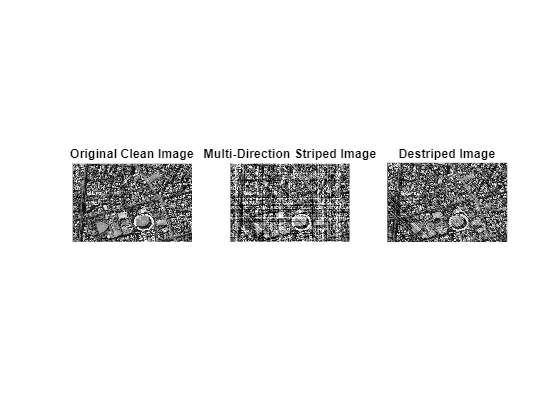

%% Display Results
figure;
subplot(1,3,1); imshow(O); title('Original Clean Image');
subplot(1,3,2); imshow(O_striped); title('Multi-Direction Striped Image');
subplot(1,3,3); imshow(destriped); title('Destriped Image');